# 关于第一次编程作业的说明：

- 请注意完成编程作业中的讨论，可以通过注释、嵌入文本、额外文件等任意形式完成；

- 在第一次编程作业中如果使用工具箱，可以通过截图等形式提交结果；

- 为了简化大家的代码过程，我向大家提供了第一次编程作业的.mlx文件，里面提供了关于.mlx文件的说明；

- 大家仍然可以使用任意形式matlab代码完成第一次编程作业，并不限制大家一定需要使用该模版，但仍然需要大家注明题号；

感谢大家的配合！

# template

- 本文件已经对每道编程题目通过分节符分节，可以单独通过”运行节“命令执行一道题目（选中）的代码，或通过”运行“命令执行整个文件；

- 关于很多同学在.mlx中遇到的图像错位问题：主要原因是在单个脚本文件中，工作区和图像设定是始终向后保持的。在之前的题目中使用subplot()画多个子图，之后的题目中画图时会出现在之前的子图中，可以在每个题目的代码前通过clf命令清除图像窗口；

%201300086 史浩男

% (a)


x = 0:pi/100:2*pi;  
y = sin(x)

y =          0    0.0314    0.0628    0.0941    0.1253    0.1564    0.1874    0.2181    0.2487    0.2790    0.3090    0.3387    0.3681    0.3971    0.4258    0.4540    0.4818    0.5090    0.5358    0.5621    0.5878    0.6129    0.6374    0.6613    0.6845    0.7071    0.7290    0.7501    0.7705    0.7902    0.8090    0.8271    0.8443    0.8607    0.8763    0.8910    0.9048    0.9178    0.9298    0.9409    0.9511    0.9603    0.9686    0.9759    0.9823    0.9877    0.9921    0.9956    0.9980    0.9995


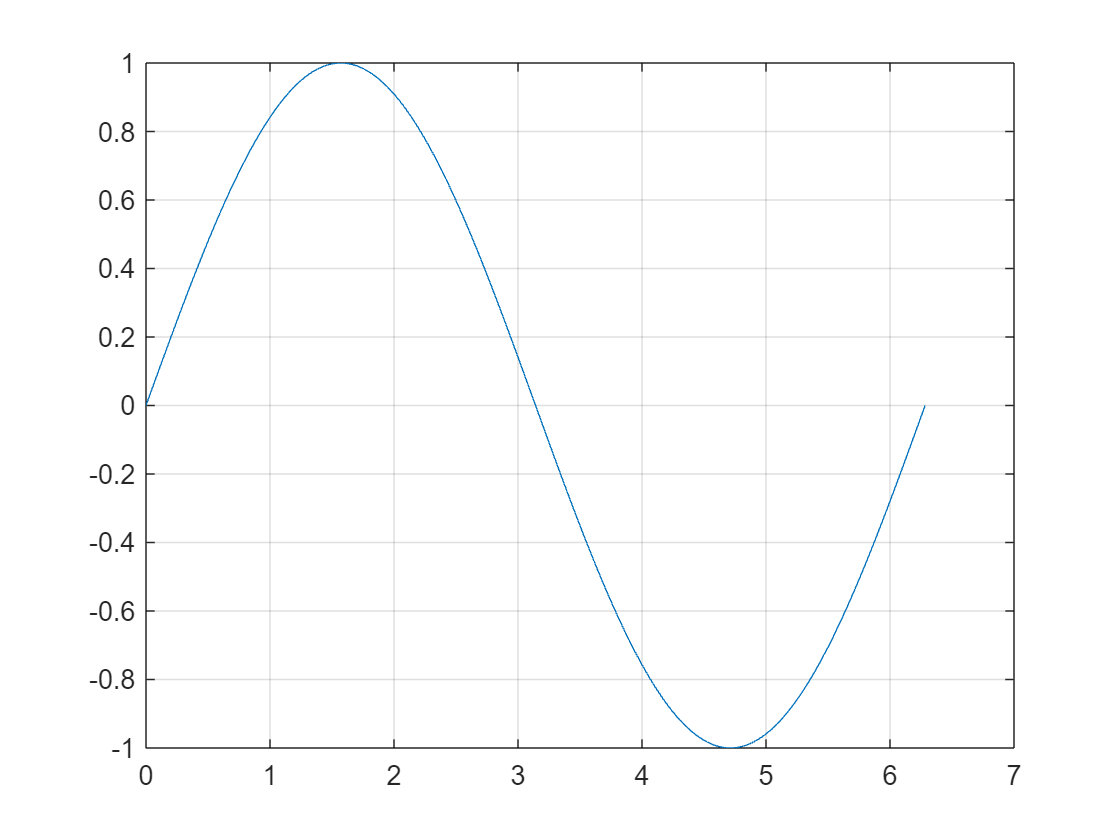

plot(x,y), grid;

% (b)
% 讨论分析

或通过内置文本讨论分析。如需插入公式，可以使用方程或LaTex方程 $F(s)=\int_0^\infty e^{-st} f(t) {\rm d}t$。

如需插入截图，直接粘贴即可。

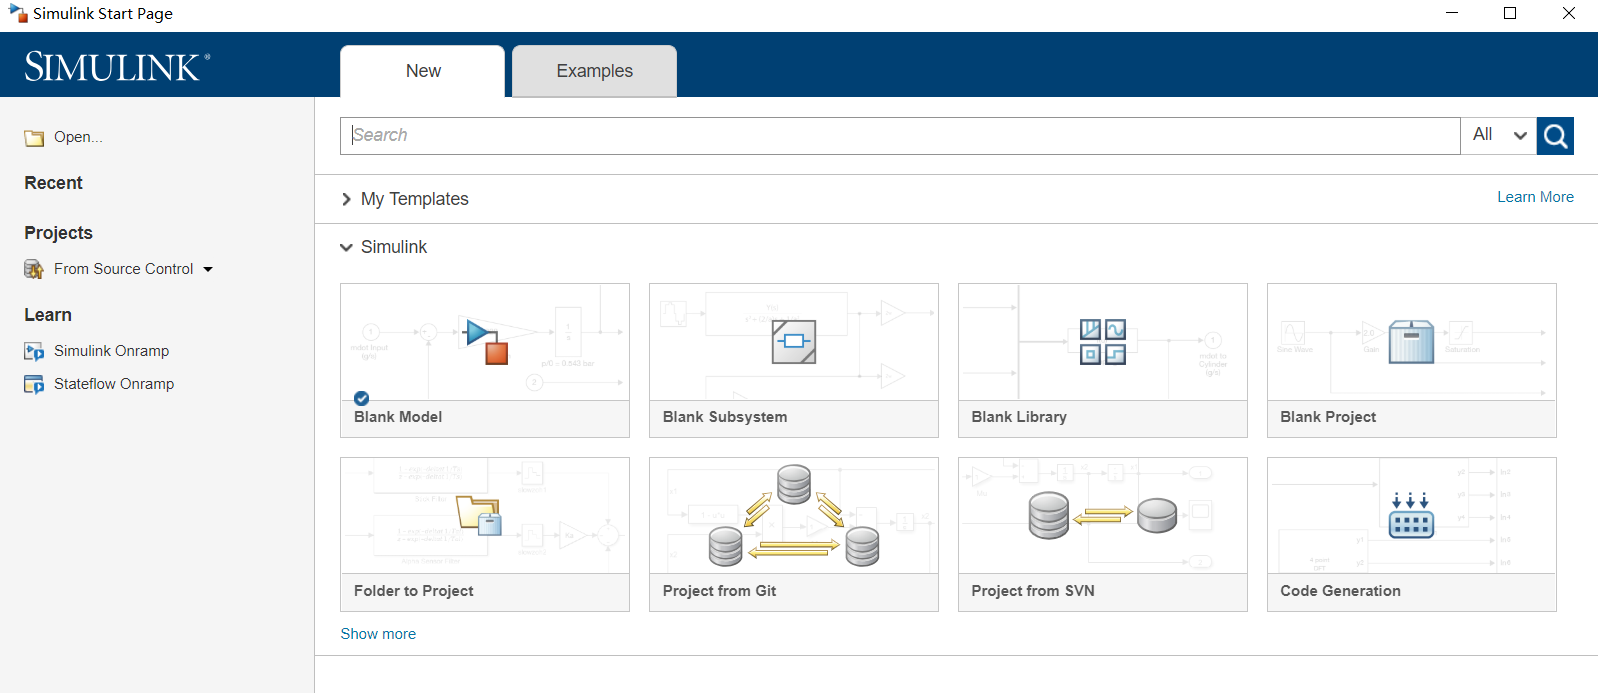

# 2-1

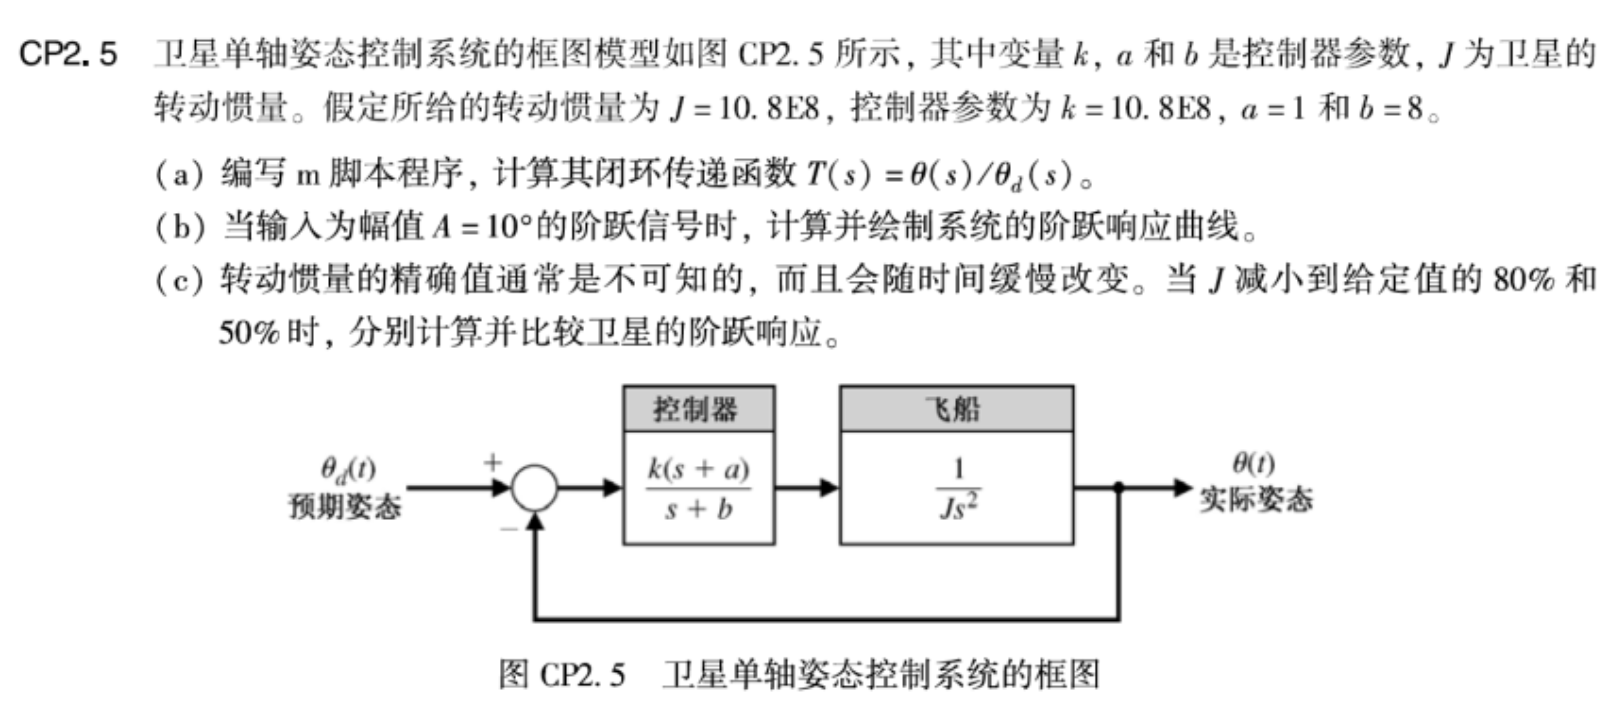

clear
clf
k=10.8E8;a=1;b=8;J=10.8E8;
num1=[k k*a];
den1=[1 b];
num2=1;
den2=[J 0 0];
[numc,denc]=series(num1,den1,num2,den2);
%Q1
sys=tf (numc, denc);
sys1=feedback(sys,1)%别忘记加反馈

sys1 =
 
                1.08e09 s + 1.08e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 1.08e09 s + 1.08e09
 
Continuous-time transfer function.



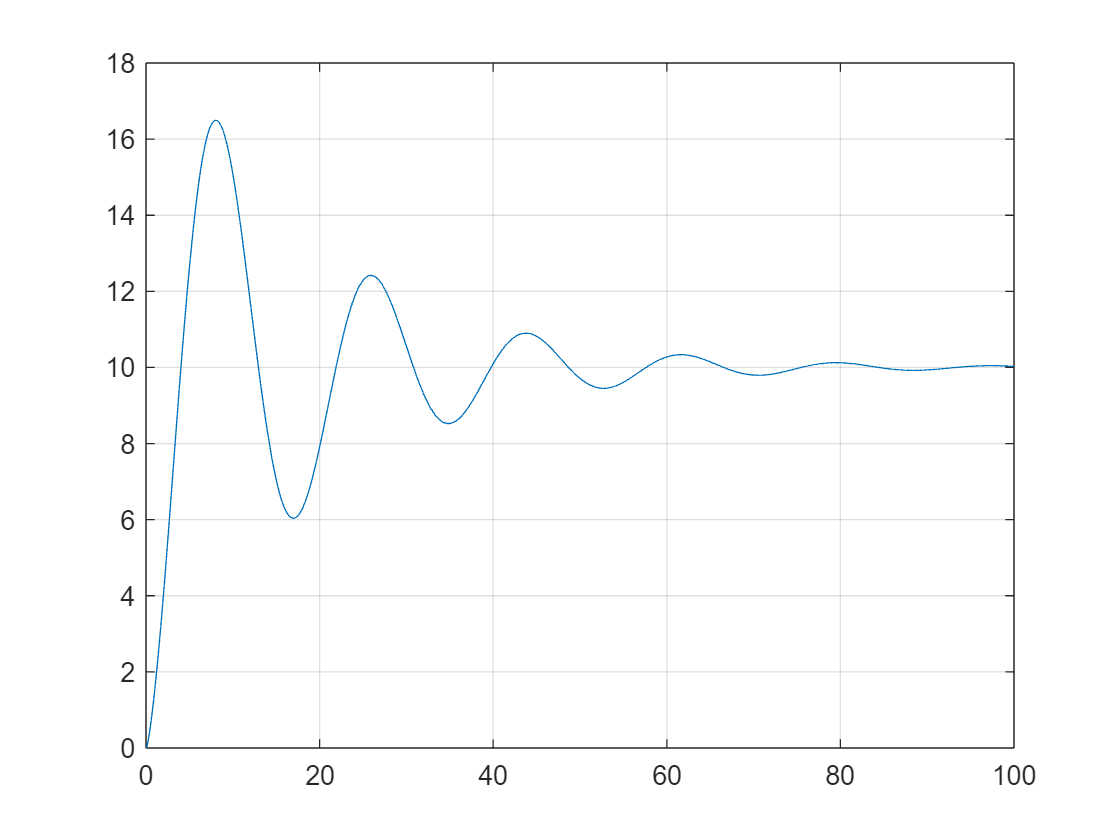

%Q2
t=[0:0.1:100];
sys2=10*sys1;%输入10幅值的阶跃，乘10即可
y=step(sys2,t);
plot(t,y),grid

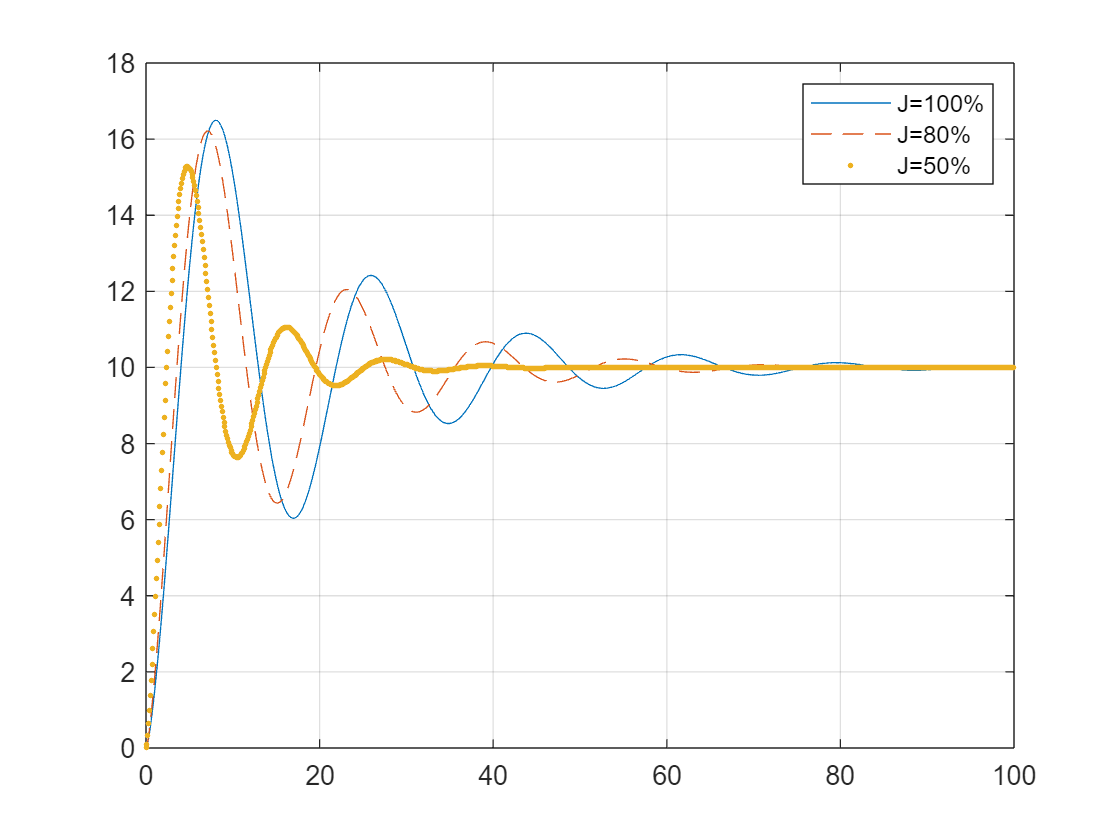

%Q3:80%
J=0.8*J;
den2=[J 0 0];
[numc,denc]=series(num1,den1,num2,den2);
sys=tf (numc, denc);
sys1=feedback(sys,1);
sys2=10*sys1;
y1=step(sys2,t);
%Q3:50%
J=0.5*J;
den2=[J 0 0];
[numc,denc]=series(num1,den1,num2,den2);
sys=tf (numc, denc);
sys1=feedback(sys,1);
sys2=10*sys1;
y2=step(sys2,t);
plot(t,y,t,y1,'--',t,y2,'.'),grid
legend('J=100%','J=80%','J=50%')

# 2-2

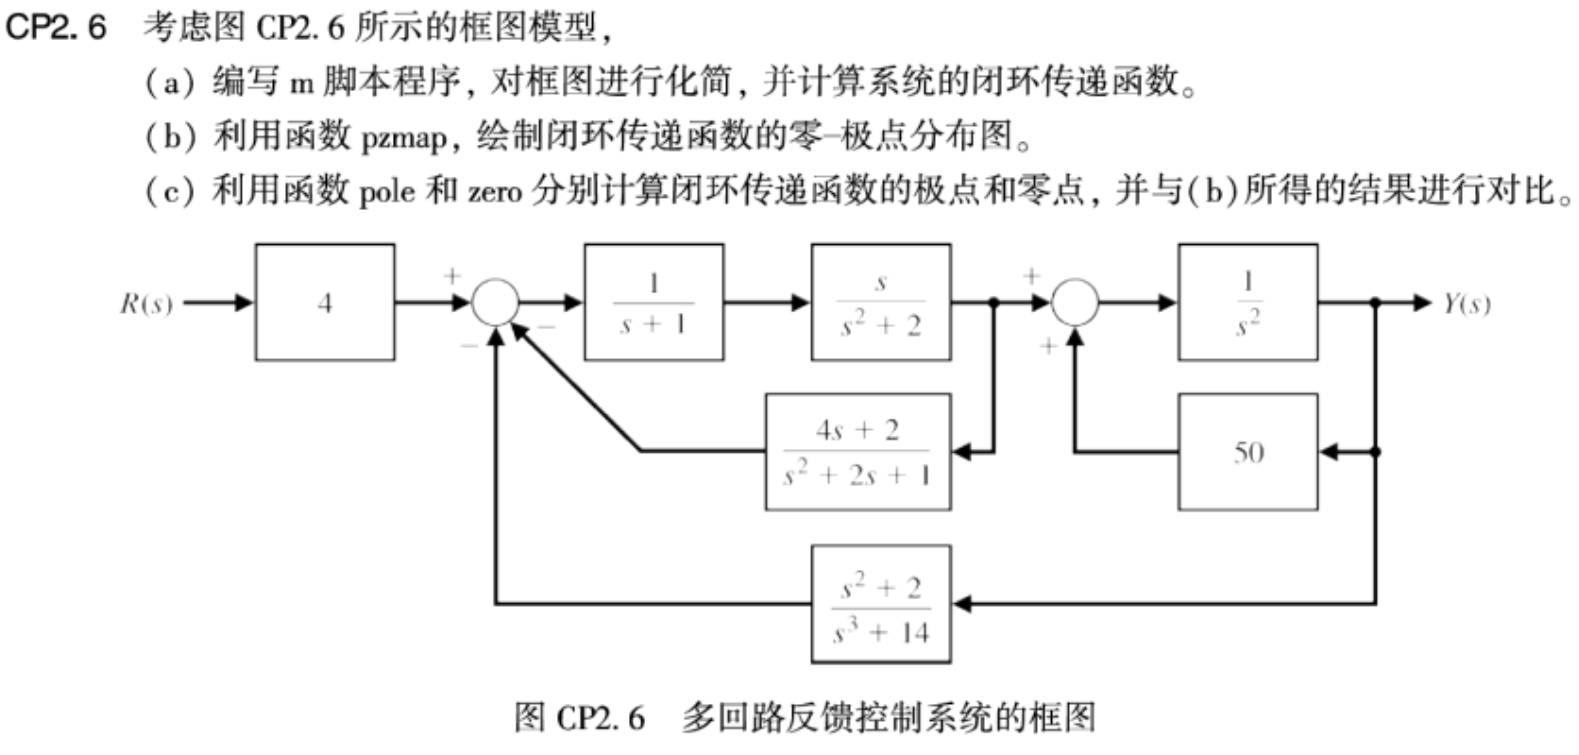

clear
clf
%Q1
num1=[1 0];den1=[1 1 2 2];
num2=[4 2];den2=[1 2 1];
sys1=tf(num1,den1);
sys2=tf(num2,den2);
sys_cl1=feedback(sys1,sys2,-1);
sys3=tf(1,[1 0 0]);
sys_cl2=feedback(sys3,50,1);
sys4=series(sys_cl1,sys_cl2);
sys5=tf([1 0 2],[1 0 0 14]);
sys_cl3=feedback(sys4,sys5,-1);
sys=series(4,sys_cl3)

sys =
 
                             4 s^6 + 8 s^5 + 4 s^4 + 56 s^3 + 112 s^2 + 56 s
  -----------------------------------------------------------------------------------------------------
  s^10 + 3 s^9 - 45 s^8 - 125 s^7 - 200 s^6 - 1177 s^5 - 2344 s^4 - 3485 s^3 - 7668 s^2 - 5598 s - 1400
 
Continuous-time transfer function.



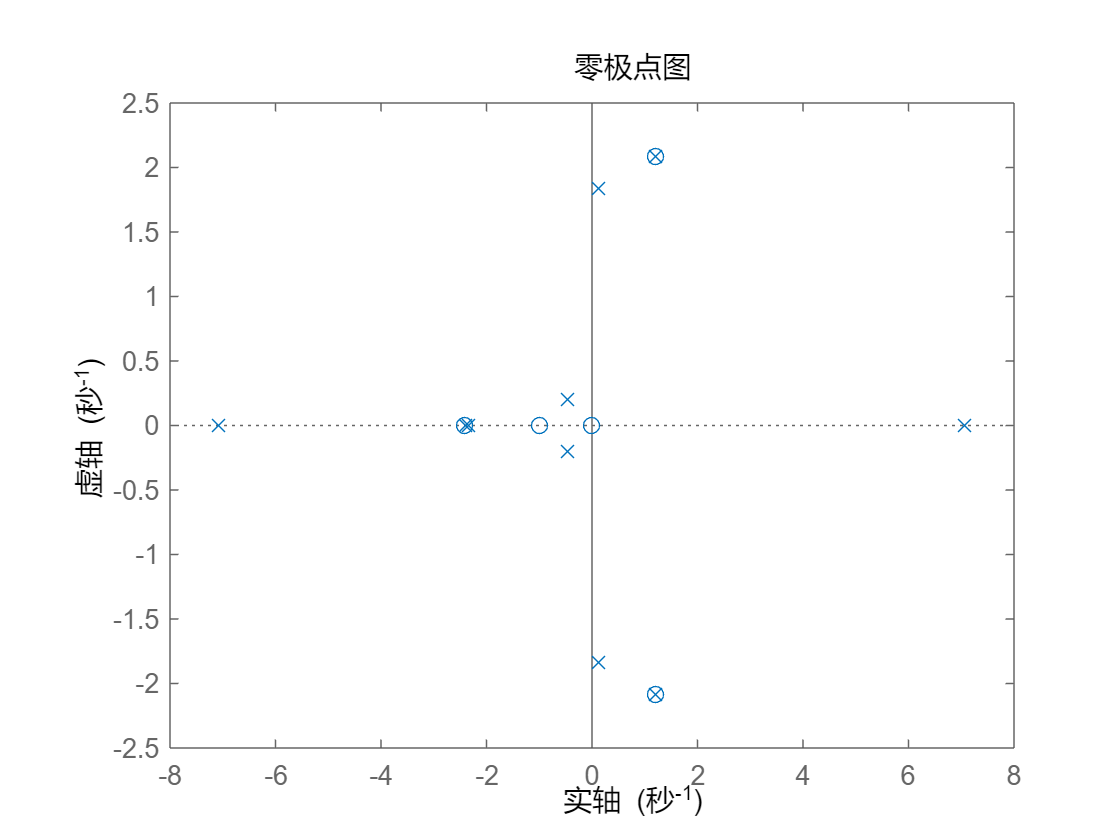

%Q2

pzmap(sys)%x极点，o零点

%Q3
zero(sys)

ans =    0.0000 + 0.0000i
   1.2051 + 2.0872i
   1.2051 - 2.0872i
  -2.4101 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


pole(sys)

ans =    7.0709 + 0.0000i
  -7.0713 + 0.0000i
   1.2051 + 2.0863i
   1.2051 - 2.0863i
   0.1219 + 1.8374i
   0.1219 - 1.8374i
  -2.3933 + 0.0000i
  -2.3333 + 0.0000i
  -0.4635 + 0.1997i
  -0.4635 - 0.1997i


y=pzmap(sys)

y =    7.0709 + 0.0000i
  -7.0713 + 0.0000i
   1.2051 + 2.0863i
   1.2051 - 2.0863i
   0.1219 + 1.8374i
   0.1219 - 1.8374i
  -2.3933 + 0.0000i
  -2.3333 + 0.0000i
  -0.4635 + 0.1997i
  -0.4635 - 0.1997i


与上一问对比结果，一致

# 2-3

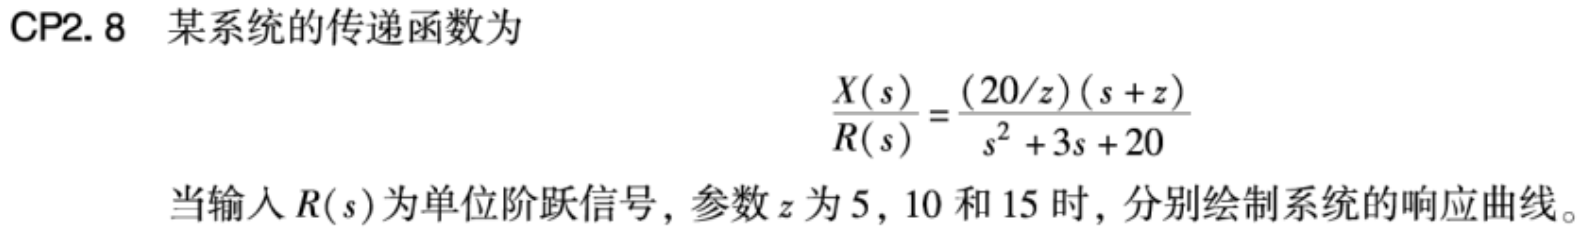

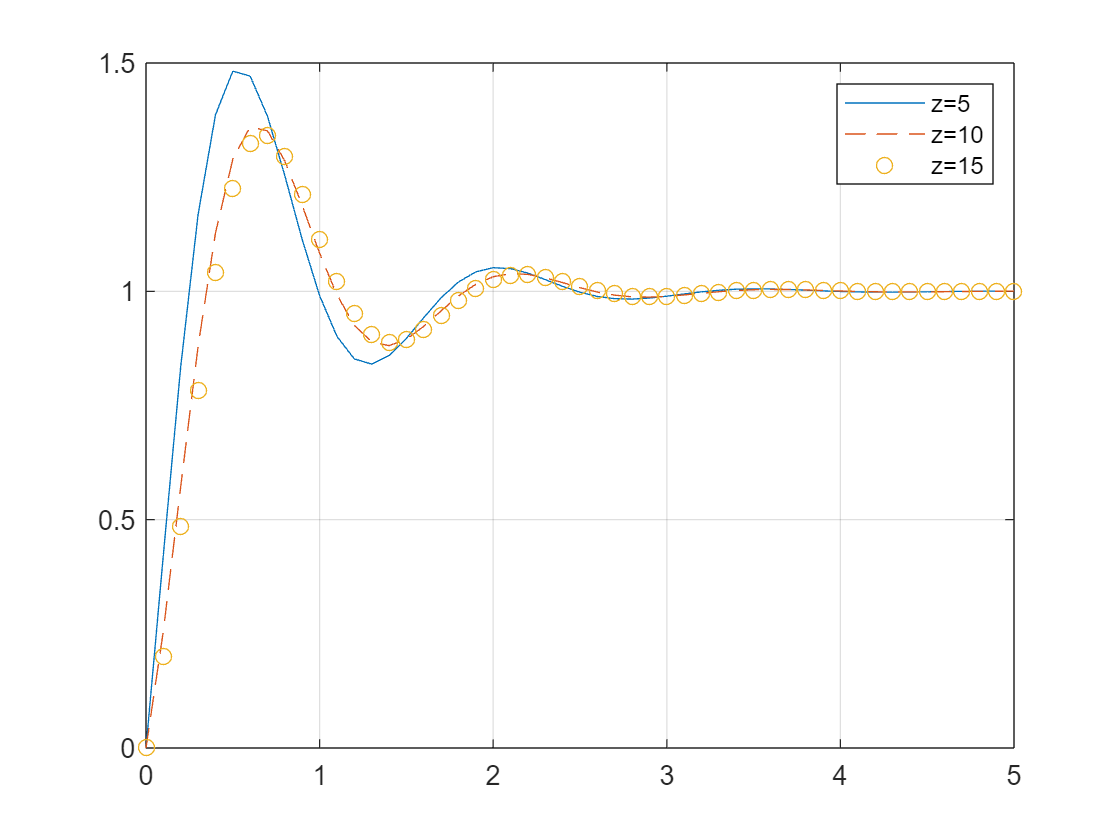

clear
%z=5
z=5;
num=[20/z 20];den=[1 3 20];
%传递函数，R(s)不用乘过去
%R(s)作用是表示是阶跃信号
sys=tf(num,den);
t=[0:0.1:5];
y1=step(sys,t);
%z=10
z=10;
num=[20/z 20];den=[1 3 20];
sys=tf(num,den);
y2=step(sys,t);
%z=15
z=15;
num=[20/z 20];den=[1 3 20];
sys=tf(num,den);
y3=step(sys,t);
plot(t,y1,t,y2,'--',t,y3,'o'),grid
legend('z=5','z=10','z=15')

# 2-4

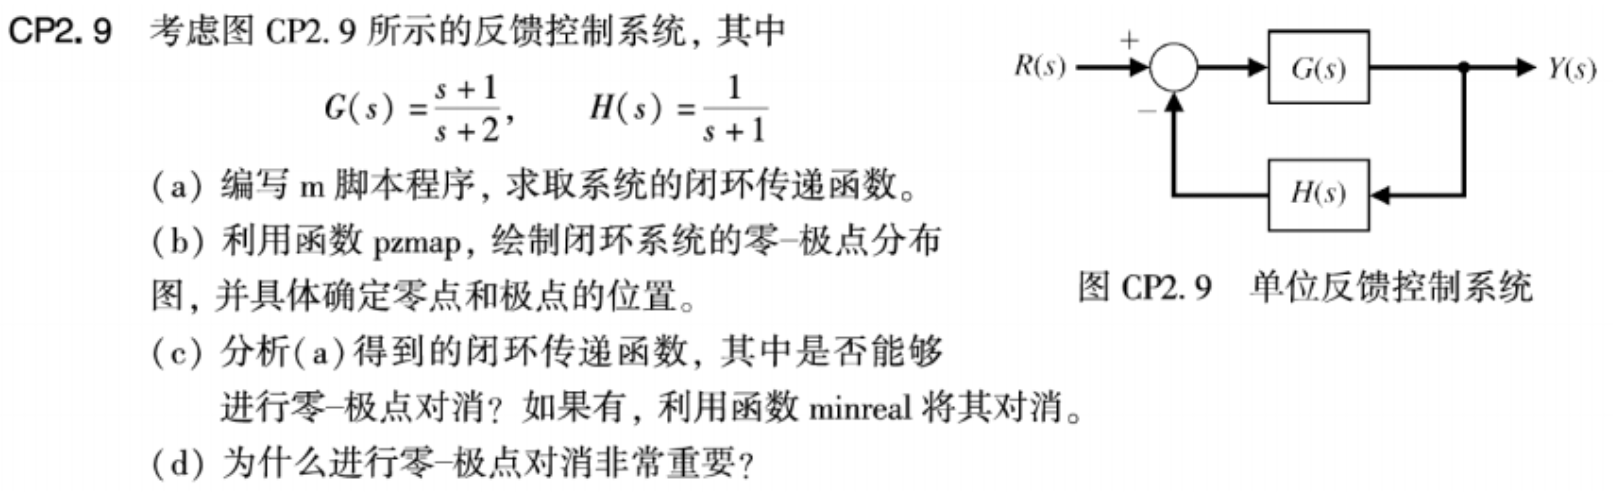

clear
%Q1
sys1=tf([1 1],[1 2]);
sys2=tf([1],[1 1]);
sys=feedback(sys1,sys2,-1)

sys =
 
  s^2 + 2 s + 1
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.



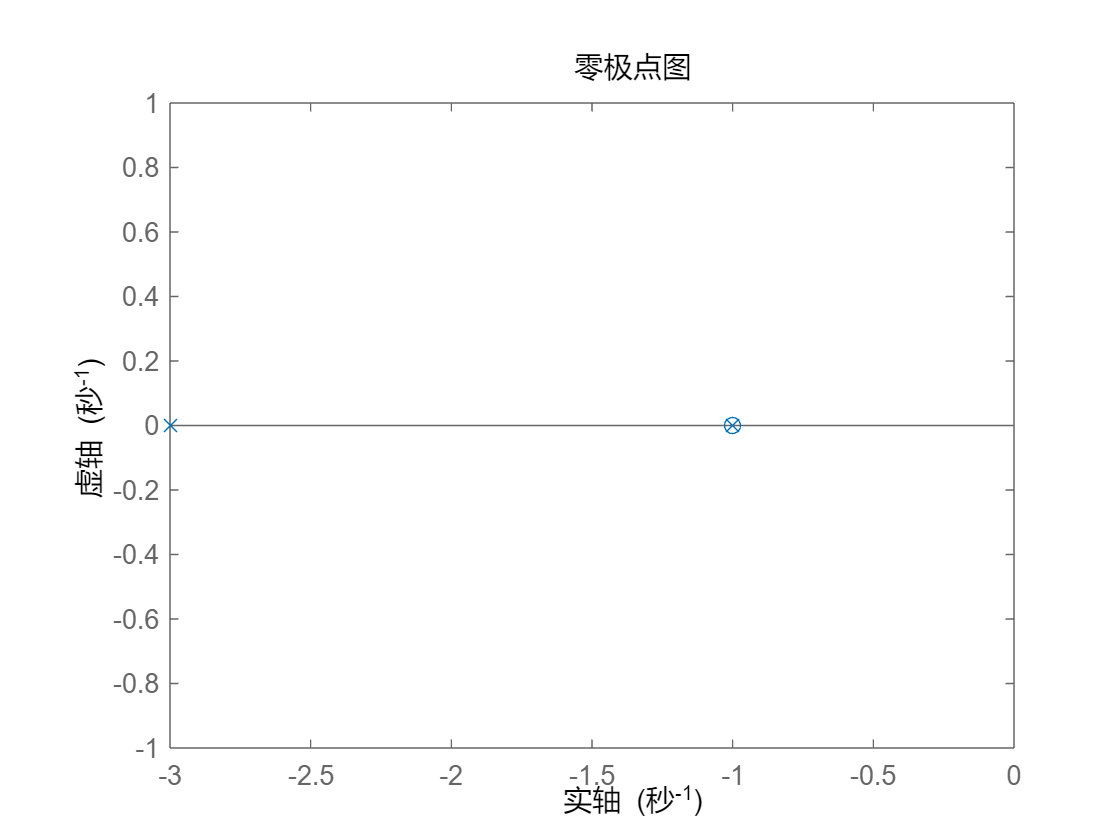

%Q2
pzmap(sys)

zero(sys)

ans =     -1
    -1


pole(sys)

ans =     -3
    -1


%Q3

能对消

sys=minreal(sys)

sys =
 
  s + 1
  -----
  s + 3
 
Continuous-time transfer function.



%Q4

如果不消掉，这个多出来的极点对系统没有任何影响。

但画根轨迹时，就会出现同一个位置既有零点又有极点的情况，可能会误判它不稳定

# 5-1

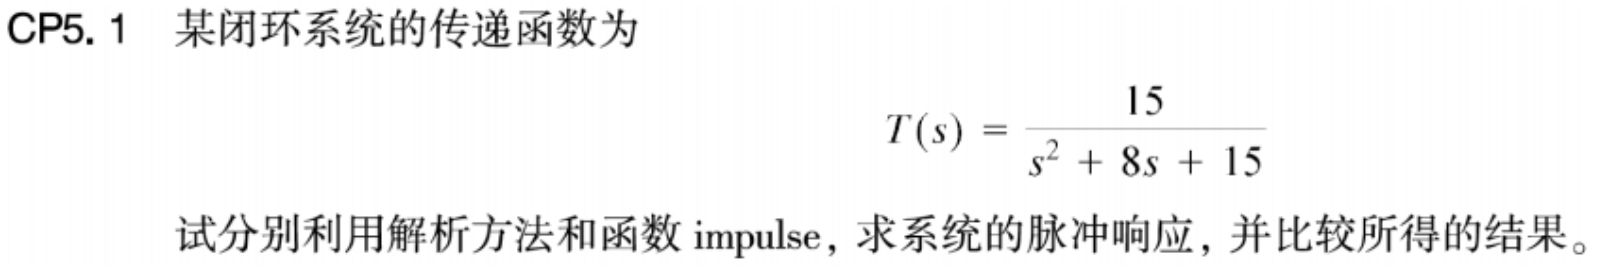

解析法结果：


$$y_t=\frac{15}{2}e^{3t}-\frac{15}{2}e^{-5t}$$


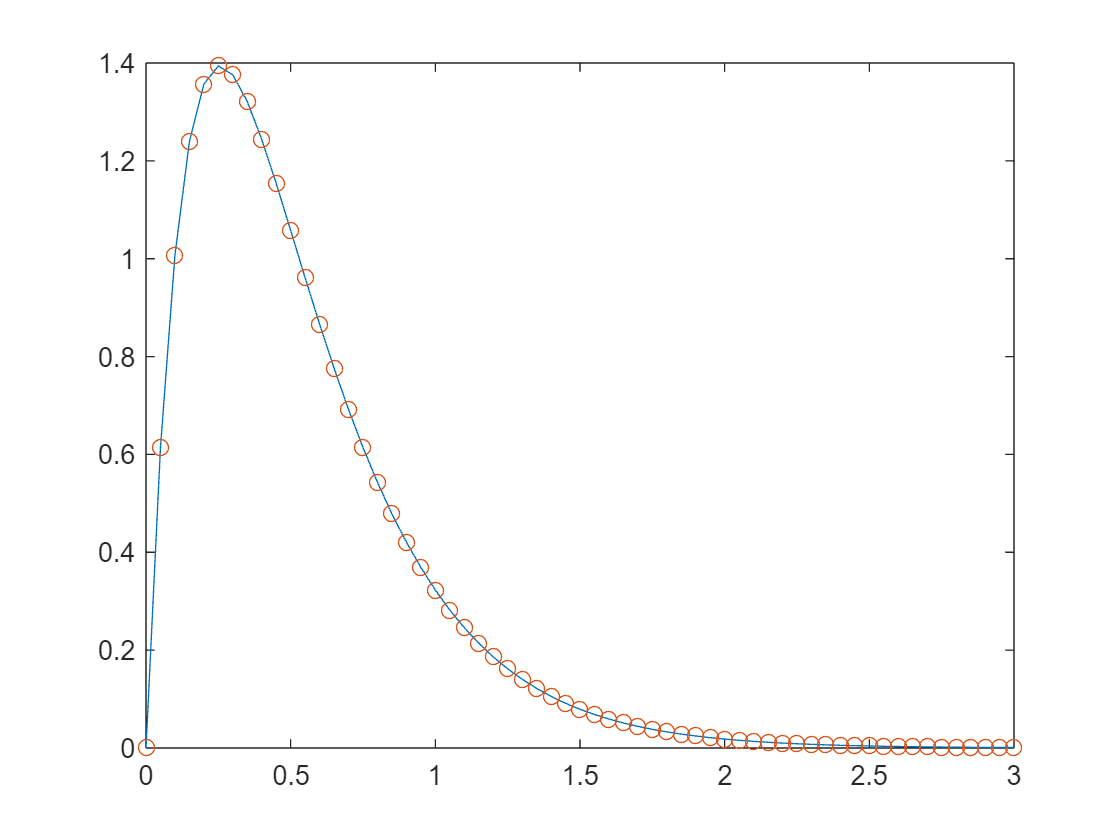

clear
clf
t=[0:0.05:3];
num=[15];den=[1 8 15];
y=impulse(num,den,t);%impulse
y_t=(15/2)*exp(-3*t)-(15/2)*exp(-5*t);%解析法结果
plot(t,y,'-',t,y_t,'o')%比较结果

# 5-2

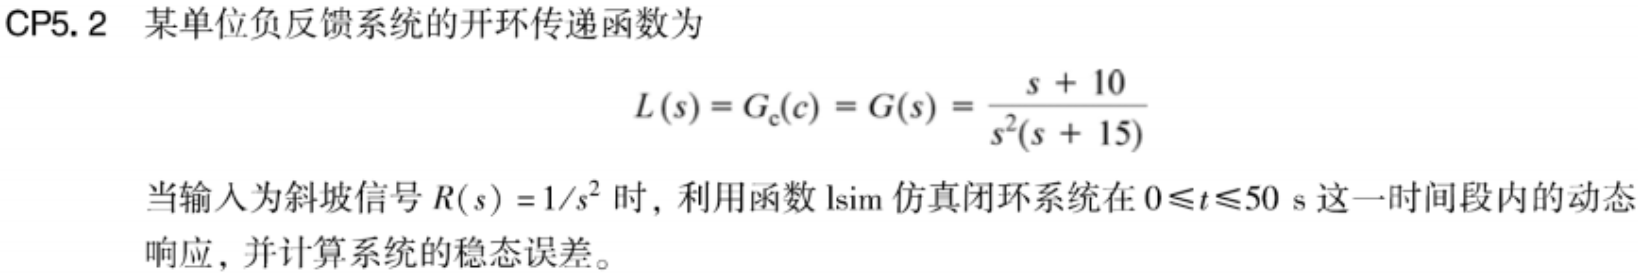

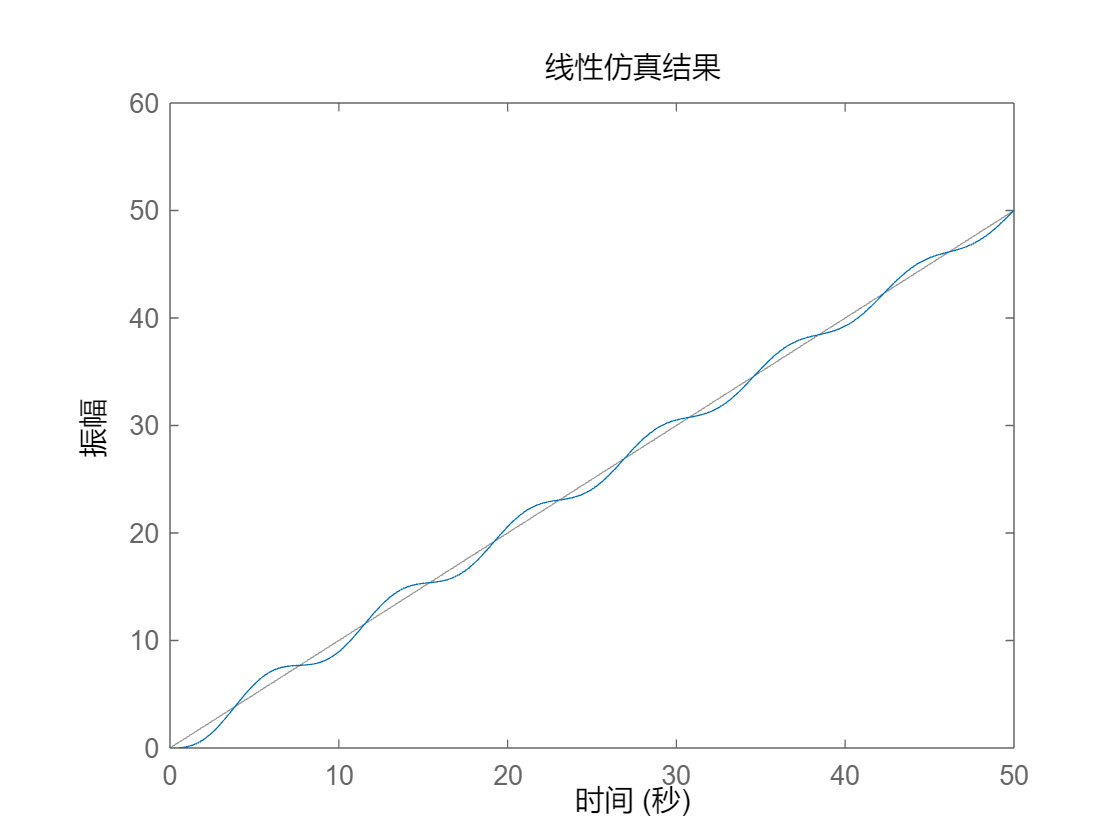

clear
clf
n=[1 10]; d=[1 15 0 0];
t=[0:0.1:50];
sys= tf(n,d);
sys_cl = feedback(sys,1);%负反馈，为什么是1？？
u=t;%斜坡信号r(t)=t
lsim(sys_cl,u,t)

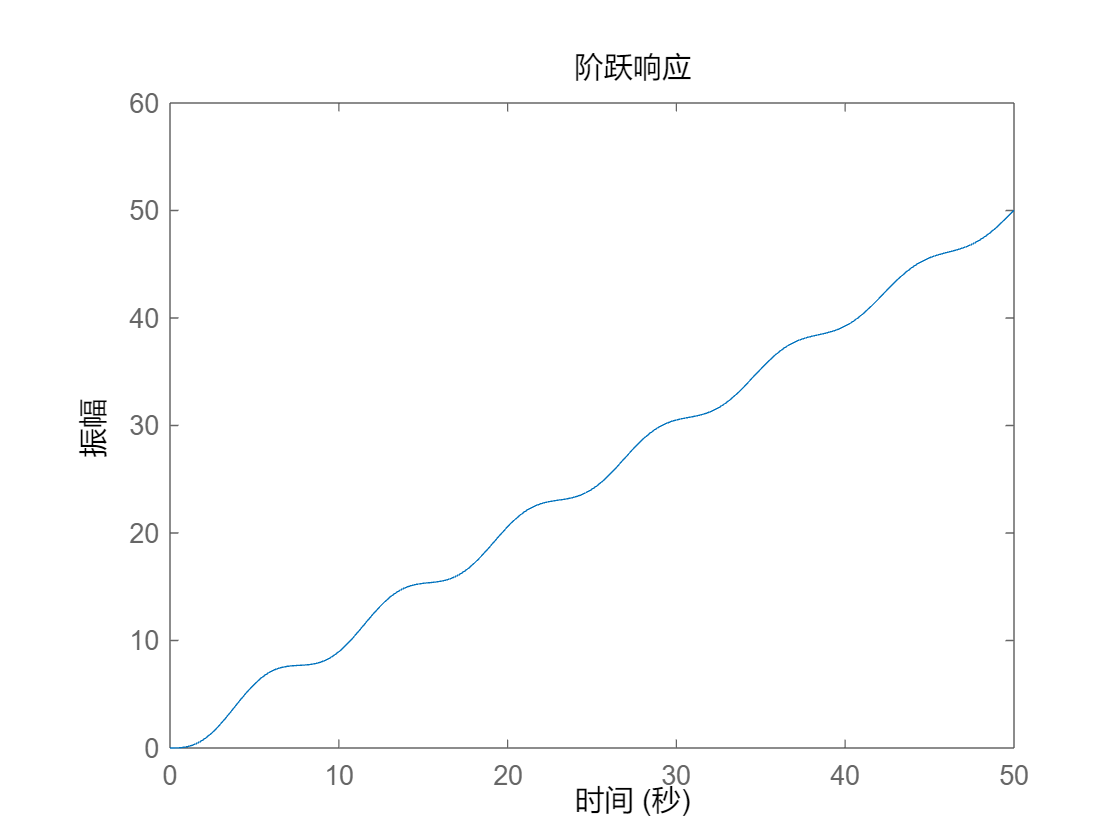

%法2，转化为阶跃信号
n=[1 10]; d=[1 15 1 10 0];
step(n,d,t)

计算稳态误差：单位斜坡II型系统，稳态误差为0

# 5-3

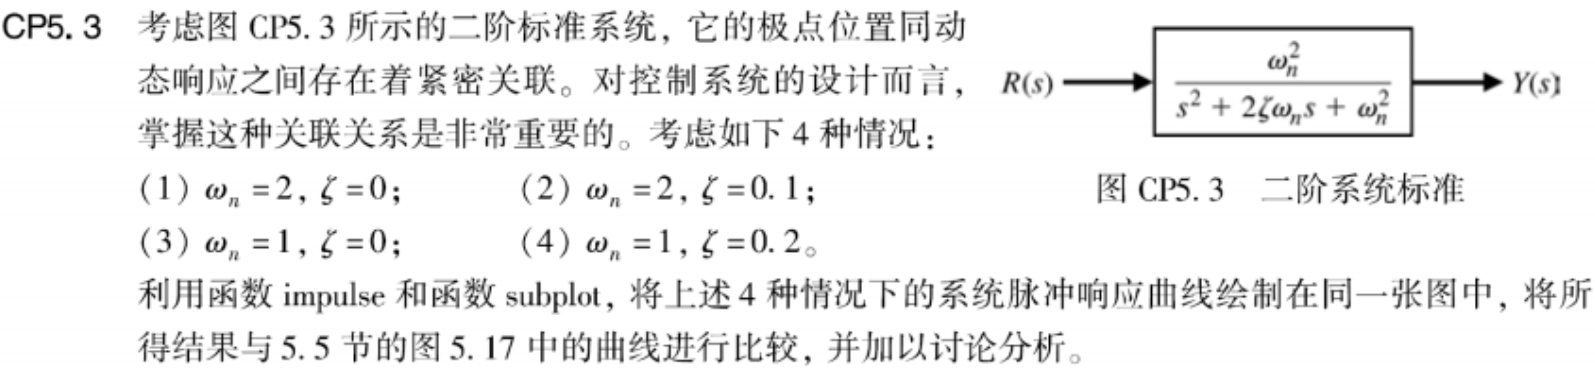

clear
clf
t=[0:0.1:30];
subplot(2,2,1)
impulse(systwo(2,0),t)

sys =
 
     4
  -------
  s^2 + 4
 
Continuous-time transfer function.



subplot(2,2,2)
impulse(systwo(2,0.1),t)

sys =
 
         4
  ---------------
  s^2 + 0.4 s + 4
 
Continuous-time transfer function.



subplot(2,2,3)
impulse(systwo(1,0),t)

sys =
 
     1
  -------
  s^2 + 1
 
Continuous-time transfer function.



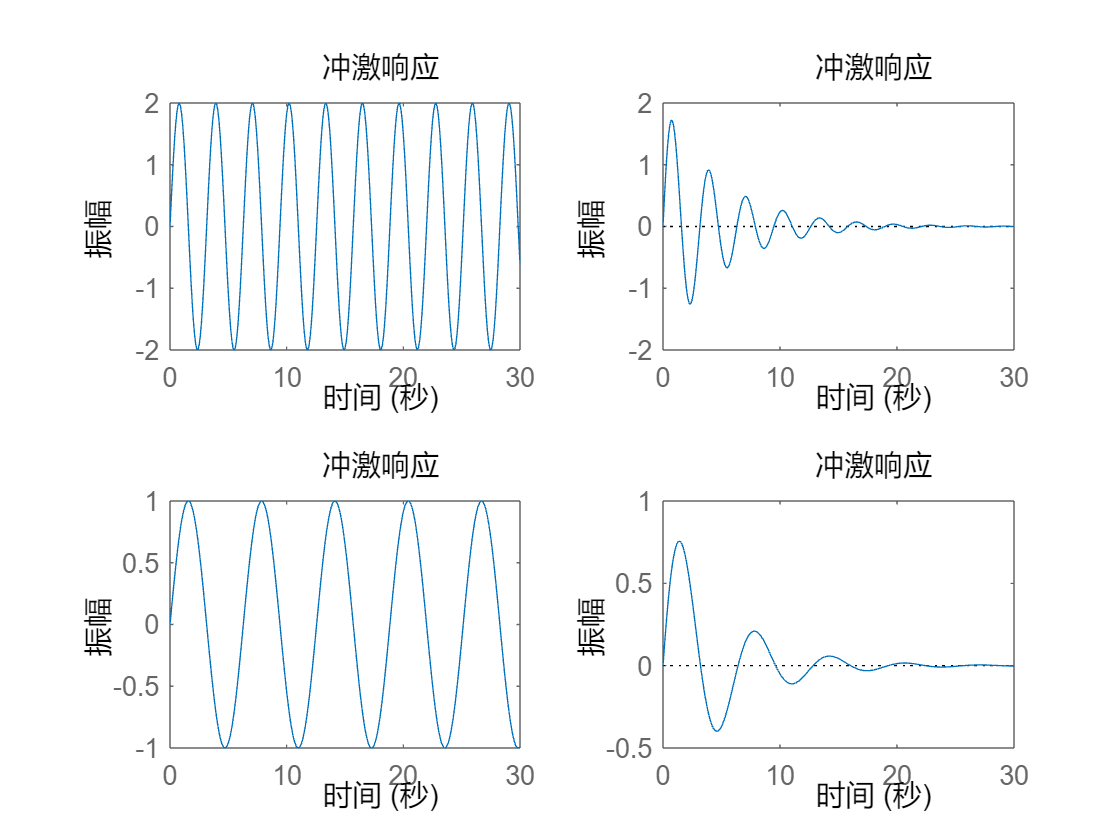

sys =
 
         1
  ---------------
  s^2 + 0.4 s + 1
 
Continuous-time transfer function.



subplot(2,2,4)
impulse(systwo(1,0.2),t)

# 5-4

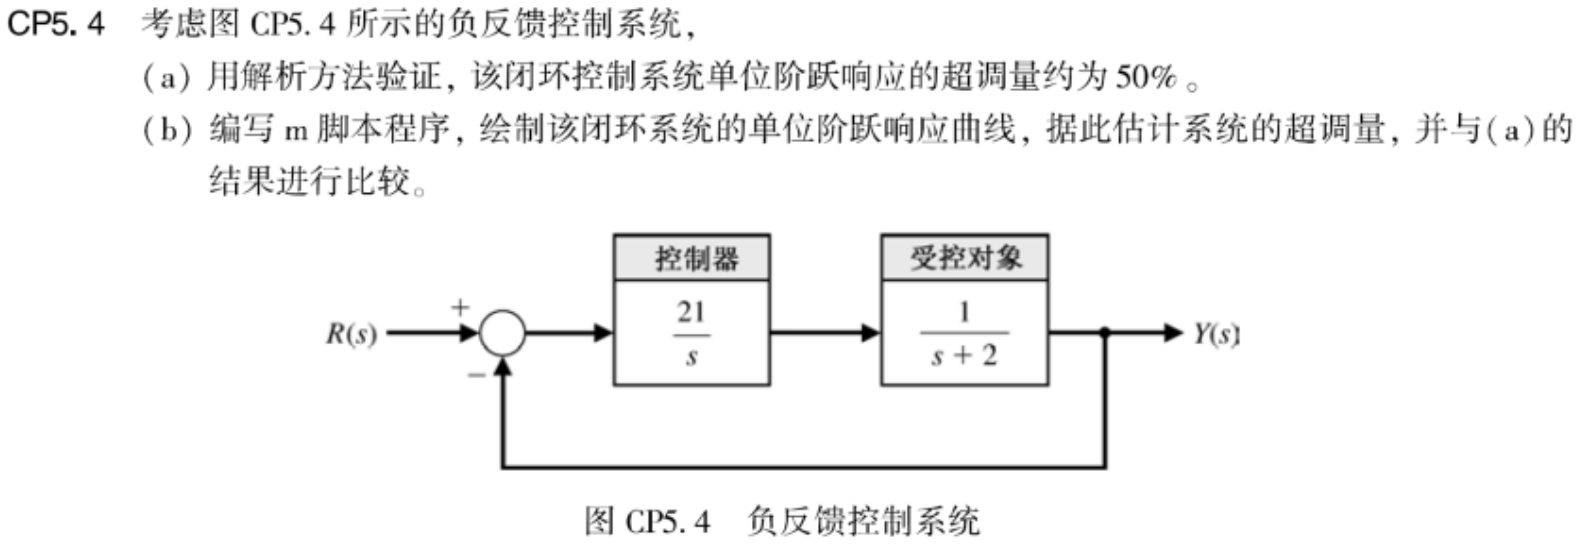

clear
%Q1解析法
w=21^0.5;j=1/w;
exp(-pi*j/(1-j^2)^0.5)*100

ans = 49.5355

求得答案为49.5355%，即约为50%

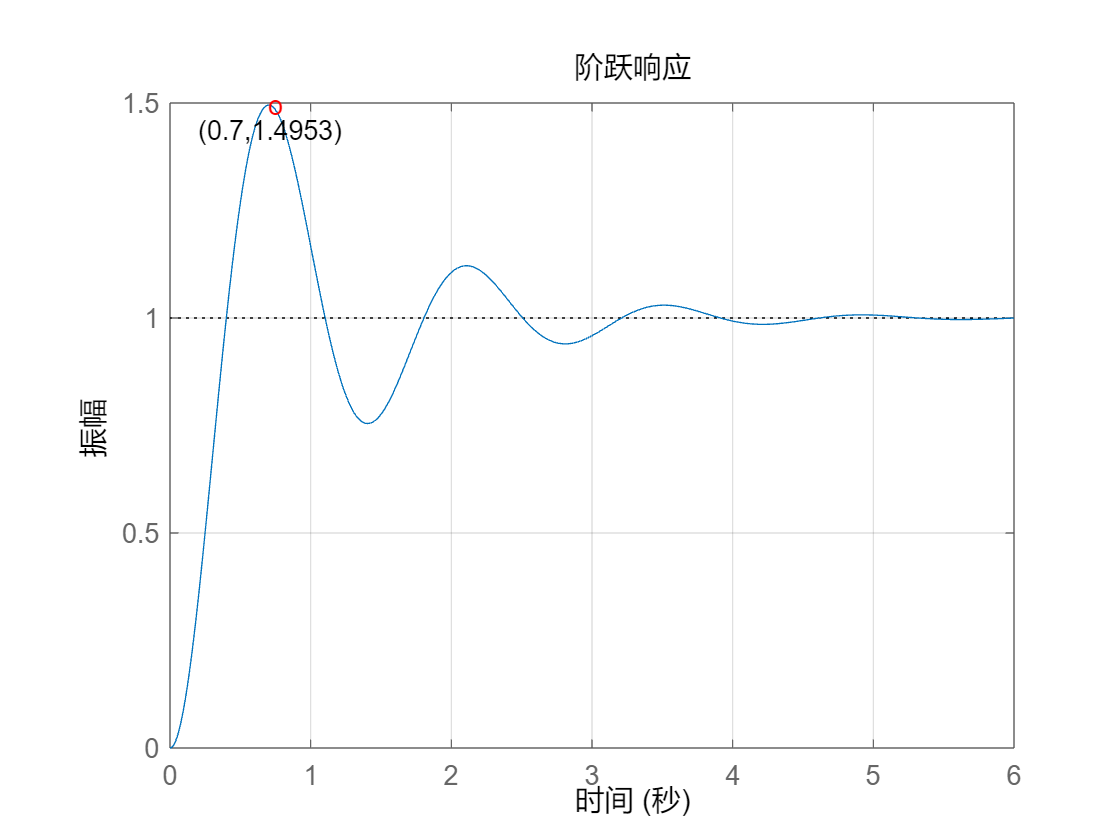

%Q2
clf
sys=tf([21],[1 2 21]);
x=[0:0.01:6];
step(sys,x)

%图像对比
R=step(sys,x);
[R_max, R_mpos] = max(R);
grid on
text(x(R_mpos),R_max,'o','color','r')
text(x(R_mpos-50), R(R_mpos-10), ['(',num2str(x(R_mpos)),',',num2str(R(R_mpos)),')'],'color','k');

# 5-5

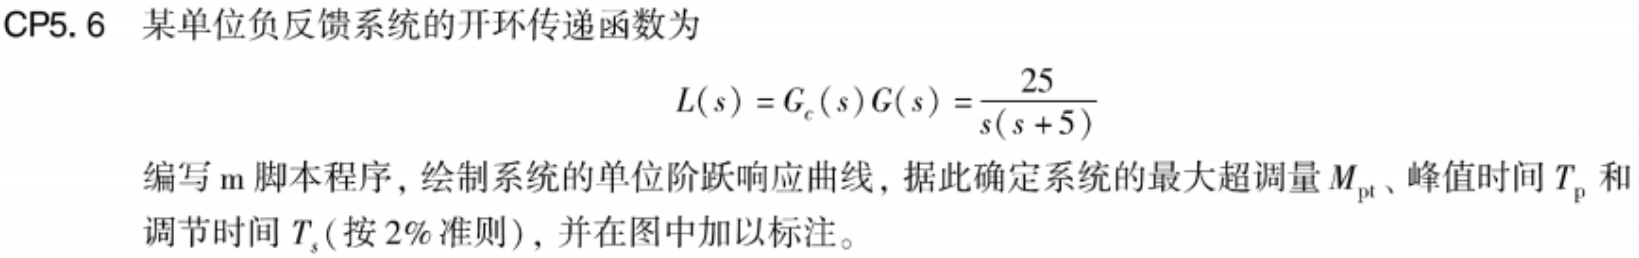

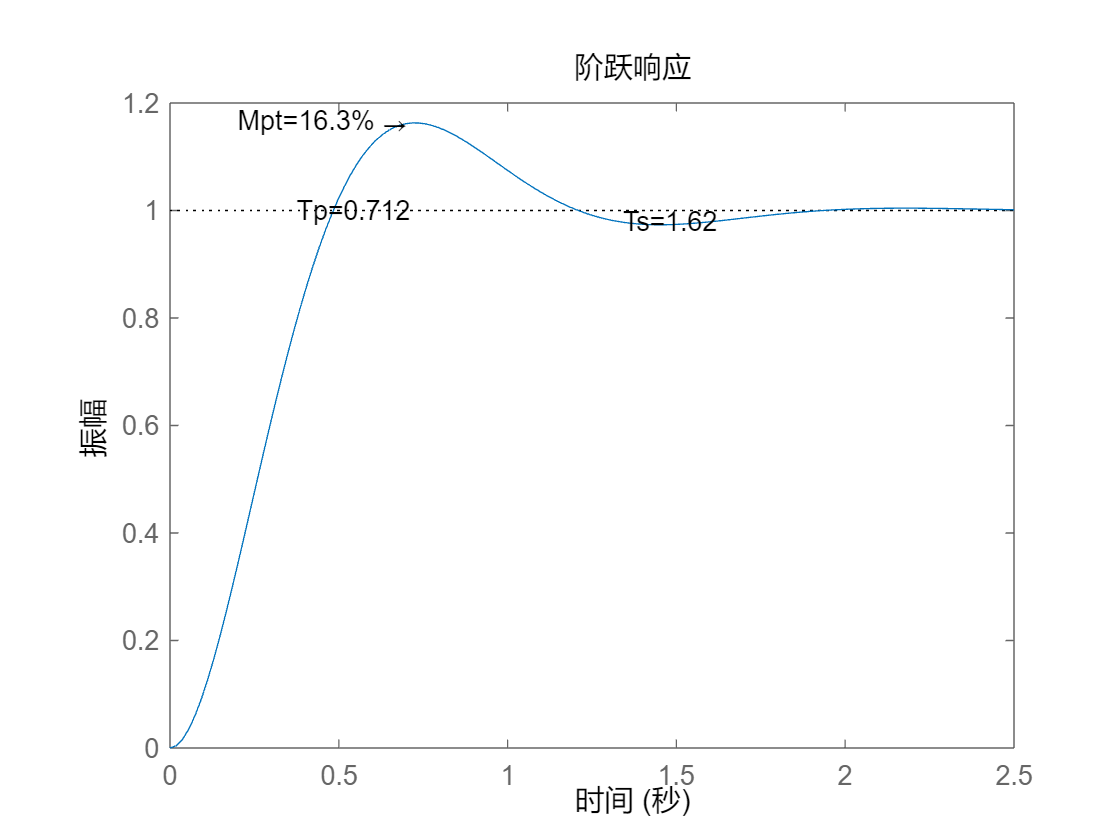

clf
clear
sys=tf([25],[1 5 0]);
sys_cl=feedback(sys,1);
step(sys_cl)
text(0.712,1.163,'Mpt=16.3%\rightarrow','horizontal','right')
text(0.712,1,'Tp=0.712','horizontal','right')
text(1.62,0.98,'Ts=1.62','horizontal','right')

# 5-6

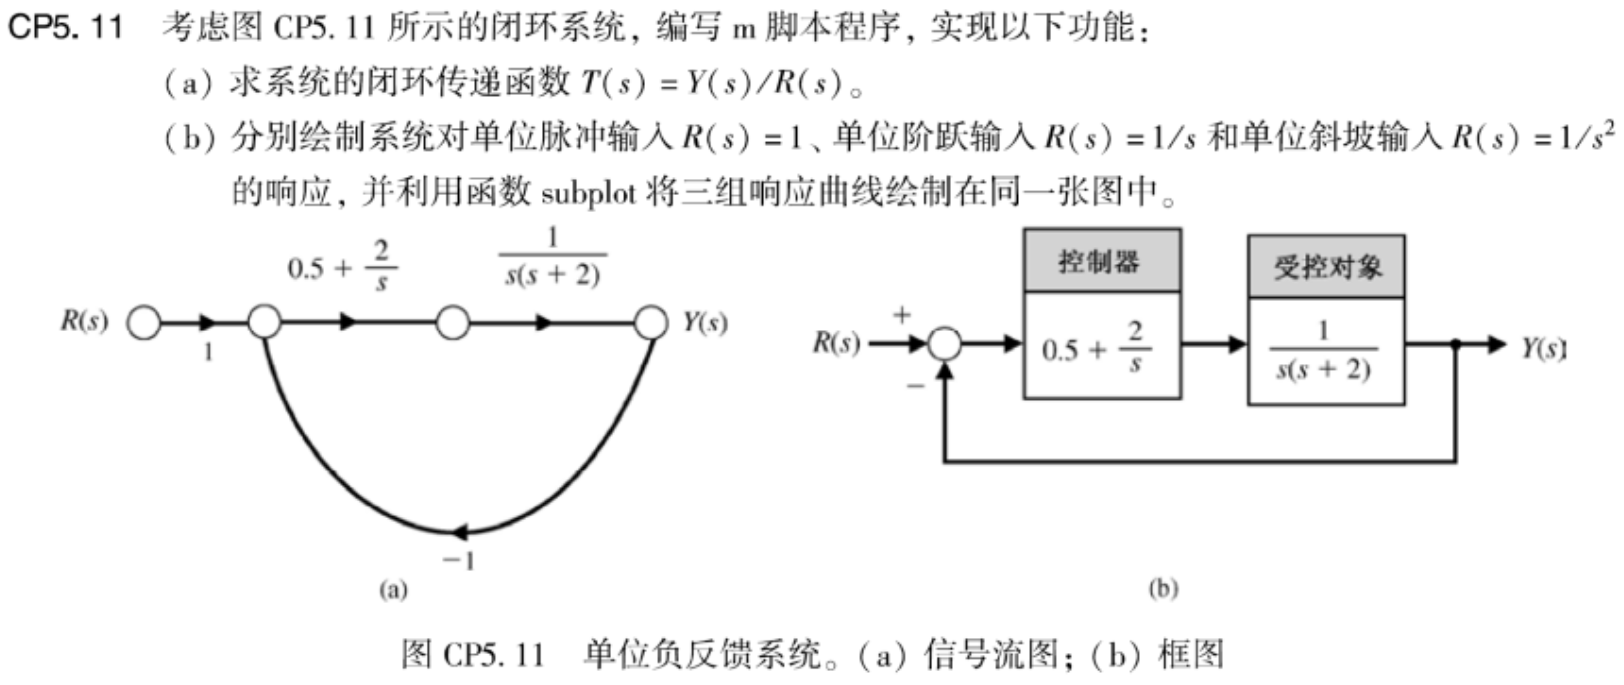

clear
%Q1
sys1=tf([1 4],[2 0]);
sys2=tf(1,[1 2 0]);
sys=series(sys1,sys2);
sys_cl=feedback(sys,1)

sys_cl =
 
          s + 4
  ---------------------
  2 s^3 + 4 s^2 + s + 4
 
Continuous-time transfer function.



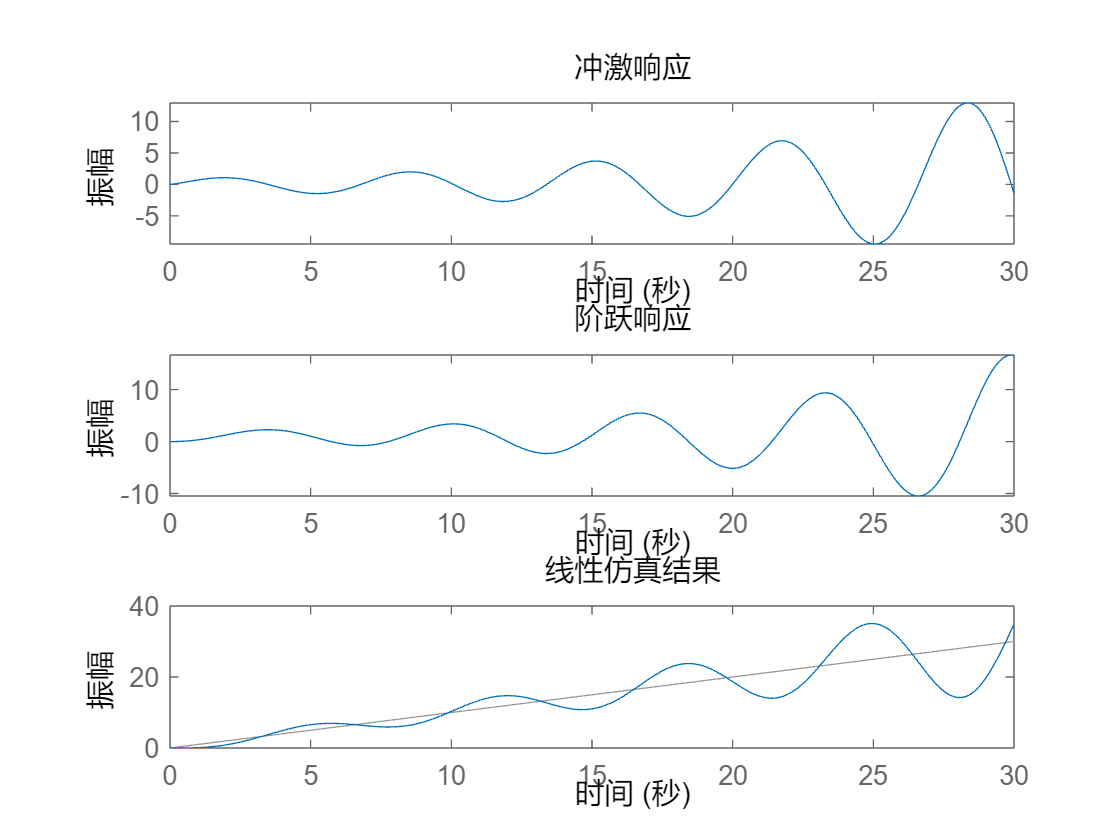


clf
%Q2
t=[0:0.1:30];
subplot(3,1,1)
impulse(sys_cl,t)
subplot(3,1,2)
step(sys_cl,t)
subplot(3,1,3)
u=t;%斜坡信号r(t)=t
lsim(sys_cl,u,t)

# 6-1

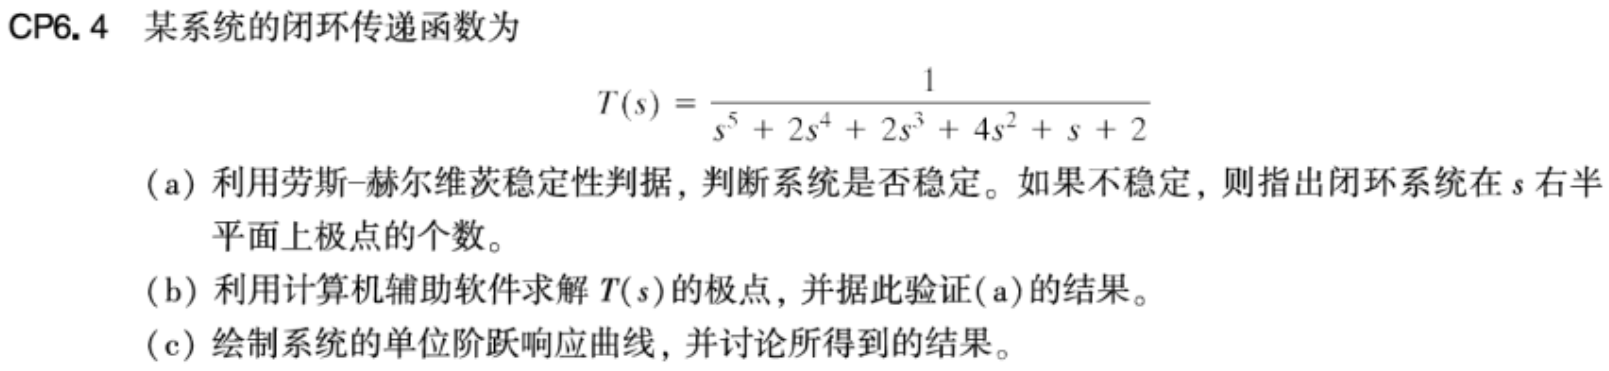

clear
%Q1


$$s^5\ |\ 1\ 2\ 1\\
s^4\ |\ 2\ 4\ 2\\
s^3\ |\ 0\ 0\ 0\\
s^2\ |\\
s^1\ |\\
s^0\ |\\
出现全0行，所以不稳定
$$


%Q2
q=[1 2 2 4 1 2];
p=roots(q)

p =   -2.0000 + 0.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


没有右平面极点，但有虚轴上极点，所以不稳定

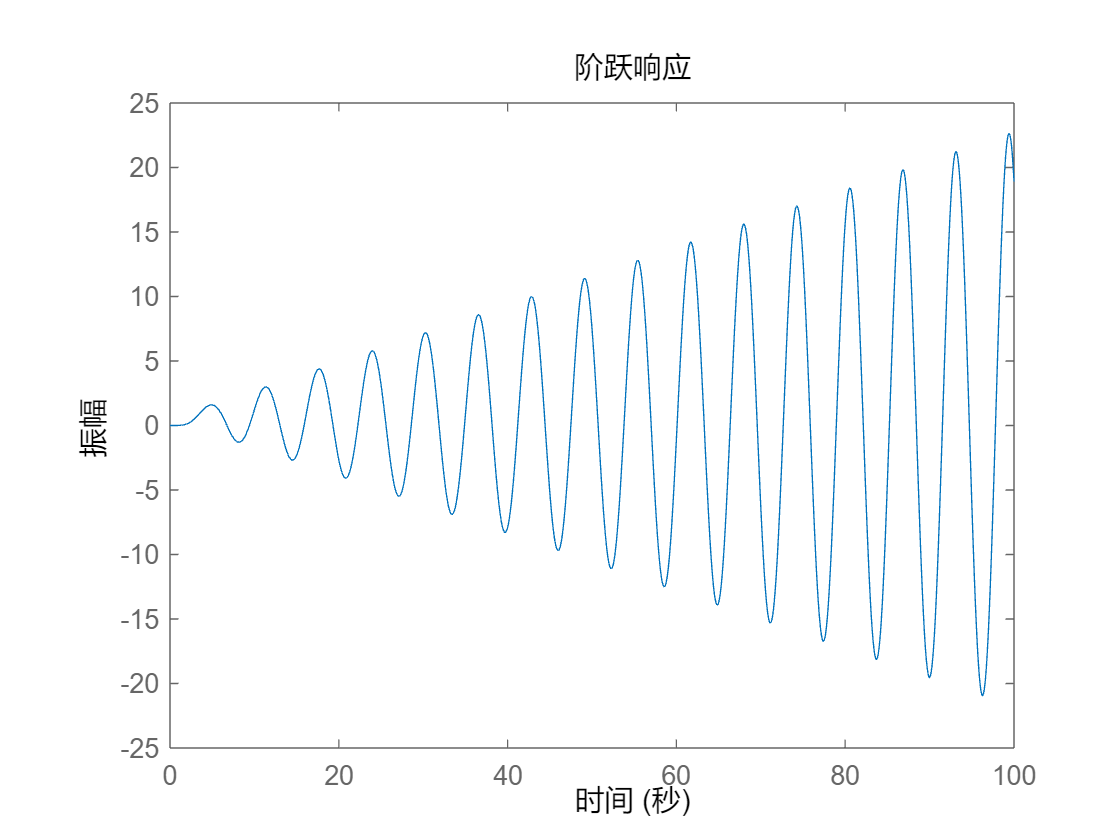

%Q3
clf
t=[0:0.1:100];
sys=tf(1,q);
step(sys,t)

# 6-2

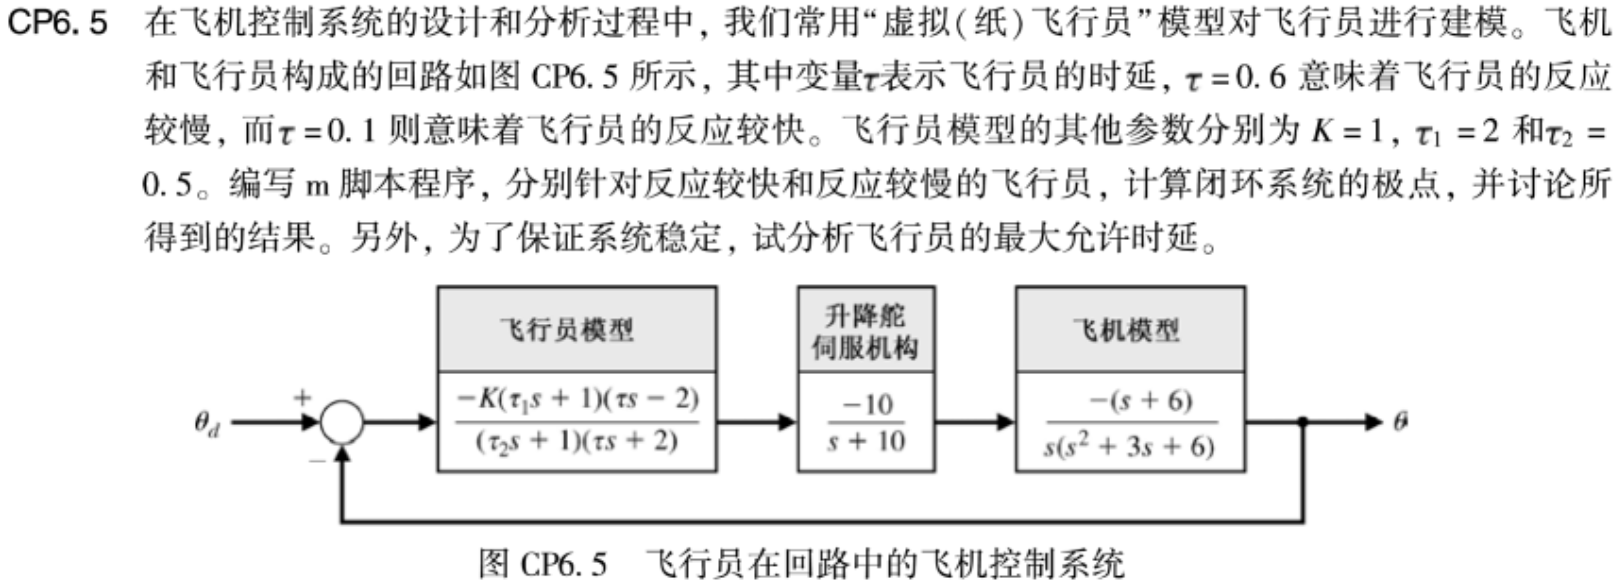

clear
K=1;t1=2;t2=0.5;
%反应慢的，有右半面极点
test_pilot(0.6)

ans =   -9.4526 + 0.0000i
  -4.5228 + 2.2595i
  -4.5228 - 2.2595i
   0.2793 + 2.0314i
   0.2793 - 2.0314i
  -0.3937 + 0.0000i


%反应快的，无右半面极点
test_pilot(0.1)

ans =  -19.6267 + 0.0000i
 -10.7712 + 0.0000i
  -3.8885 + 0.0000i
  -0.1697 + 2.7880i
  -0.1697 - 2.7880i
  -0.3742 + 0.0000i


%计算最大时延
t=[0.1:0.0001:0.6];
for i=1:length(t)
    realmax=max(real(test_pilot(t(i))));
    if realmax>=0 
        t(i)%最大时延
        break;
    end;
end;

ans = 0.2044

# 6-3

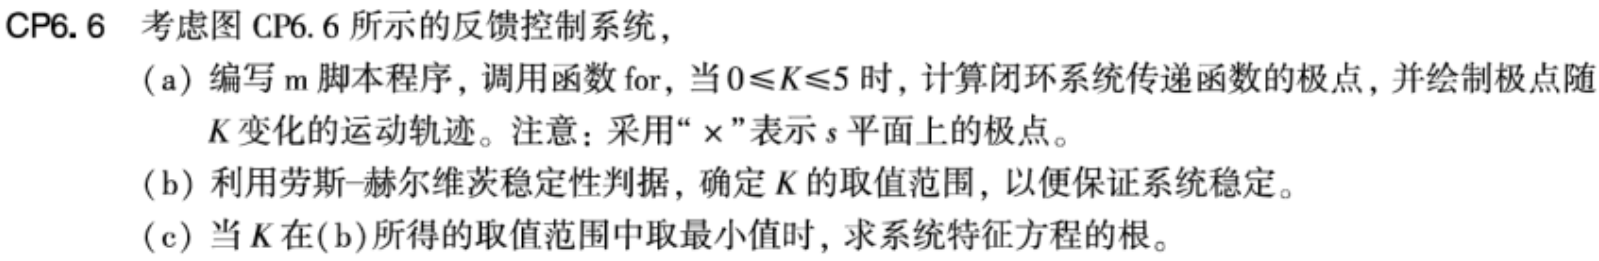

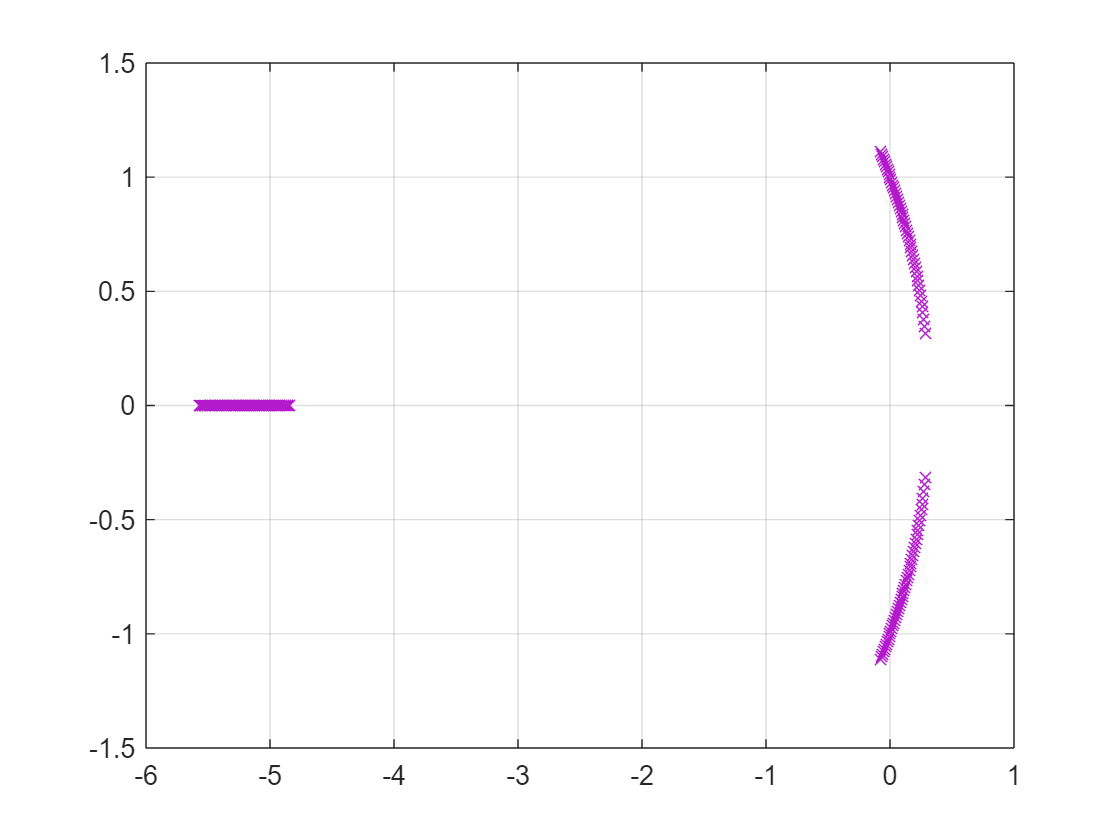

clear
%Q1
K=[0:0.1:5];
%不能直接从开环传递函数取特征方程
for i=1:length(K)
    sys=tf(1,[1 5 K(i)-3 K(i)]);
    sys=feedback(sys,1);
    p(:,i)=pole(sys);
end
clf
plot(real(p),imag(p),'x','Color',[0.7,0.1,0.8]),grid

%Q2


$$闭环传递函数为\frac{1}{s^3+5s^2+(K-3)s+K+1}$$



$$s^3\ |\ 1\ K-3\\
s^2\ |\ 5\ K+1\\
s^1\ |0.8K-3.2\ 0\\
s^0\ |\\

解得K>4$$


%解析方法：
K=[-5:0.1:5];
for i=1:length(K)
    sys=tf(1,[1 5 K(i)-3 K(i)]);
    sys=feedback(sys,1);
    p=pole(sys);
    realmax=max(real(p));
    if realmax<0 
        K(i-1)
        break;
    end
end

ans = 4

%求得的范围是K>=4
%Q3
K=4;
sys=tf(1,[1 5 K-3 K]);
sys=feedback(sys,1);
p=pole(sys)

p =   -5.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


# 6-4

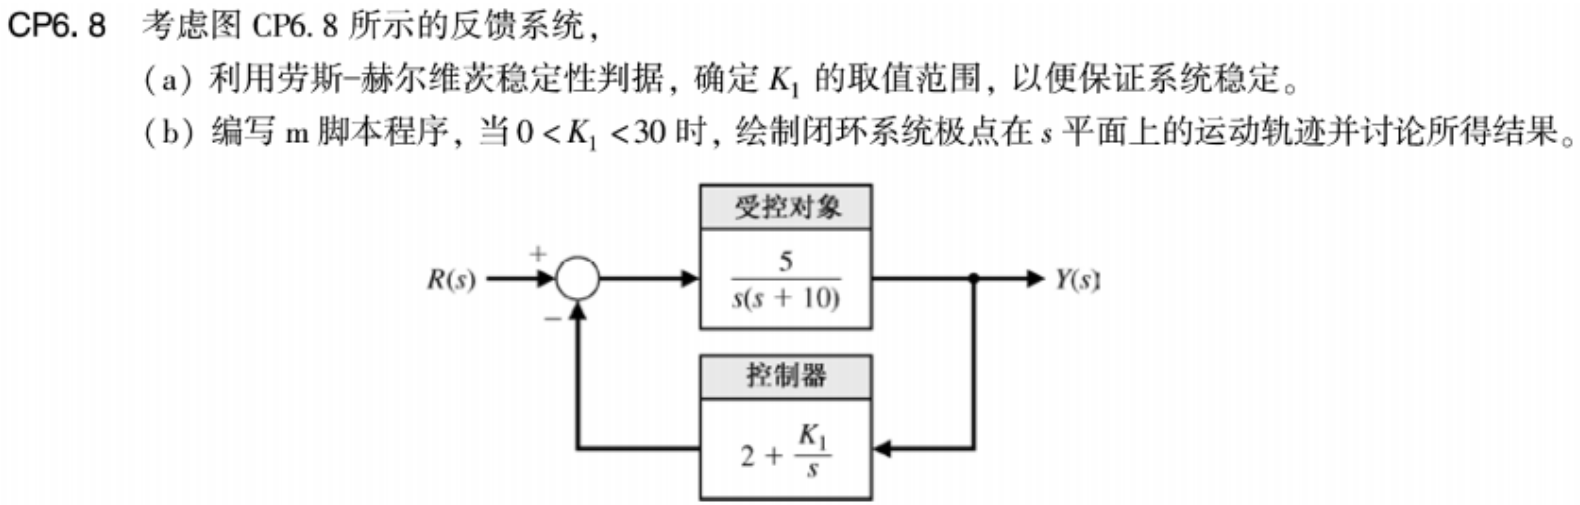

clear
%Q1


$$闭环传递函数为\frac{\frac{5}{s(s+10)}}{1+\frac{5}{s(s+10)}*\frac{2s+K}{s}}=\frac{5s}{s^3+10s^2+10s+5K}\\
s^3\ |\ 1\ 10\\
s^2\ |\ 10\ 5K\\
s^1\ |10-0.5K\ 0\\
s^0\ |5K \ 0\\

解得K>0\ & K<20$$


K=[0:0.1:30];
sys1=tf(5,[1 10 0]);
for i=1:length(K)    
    sys2=tf([2 K(i)],[1 0]);
    sys=feedback(sys1,sys2,-1);
    q=sys.den{1};
    p=roots(q);
    realmax=max(real(p));
    if realmax>0 
        K(i-1)
        break;
    end
end

ans = 19.9000

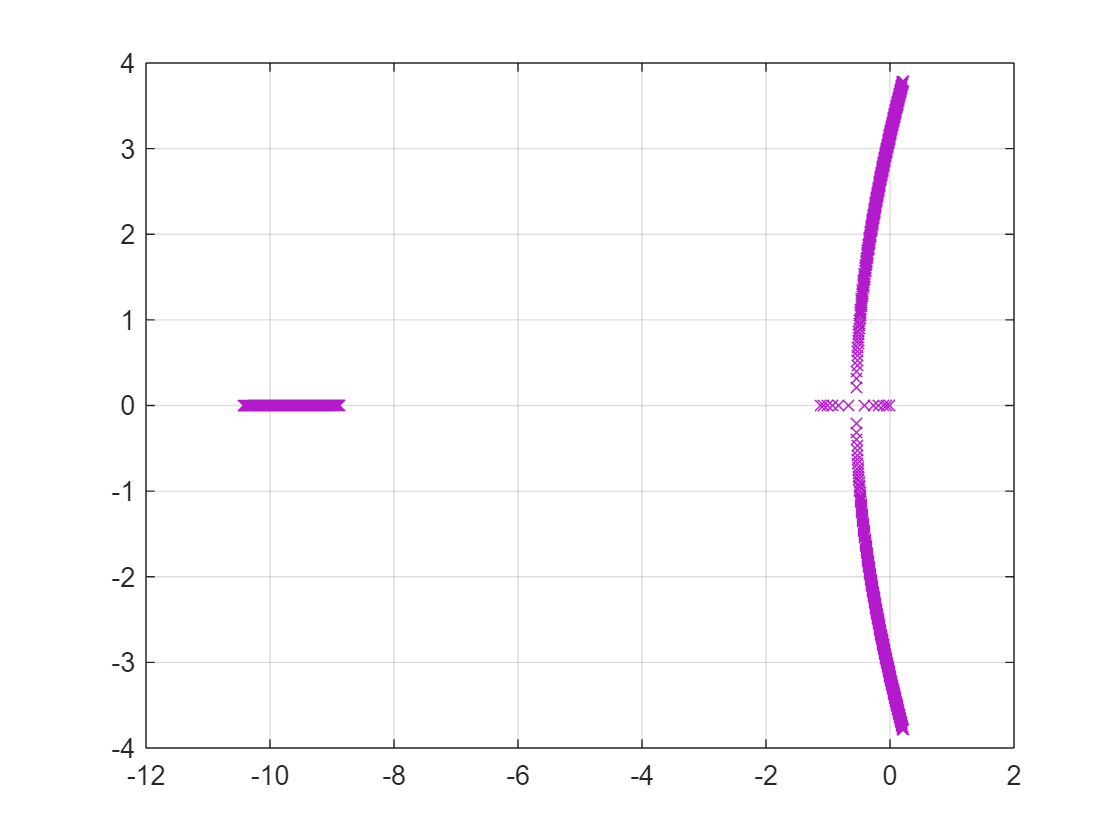

%解得范围为K1>0,K1<20
%Q2
for i=1:length(K)    
    sys2=tf([2 K(i)],[1 0]);
    sys=feedback(sys1,sys2,-1);
    p(:,i)=pole(sys);
end
clf
plot(real(p),imag(p),'x','Color',[0.7,0.1,0.8]),grid